%% DC gearmotor + encoder model for flap position control
clear; clc;

%% -------------------------
%  Datasheet values
%% -------------------------
gear_ratio      = 90;          % 90:1
n0_rpm_out      = 122;         % no-load speed at gearbox shaft [rpm]
I0              = 0.350;       % no-load current [A]
V_start         = 1.0;         % start voltage [V]
tau_stall_kgcm  = 38;          % stall torque [kgf*cm]  <-- assumed
I_stall         = 7.0;         % stall current [A]

enc_cpr_motor   = 16;          % CPR at motor shaft
enc_cpr_out     = 1440;        % CPR at gearbox shaft

%% -------------------------
%  USER INPUTS / ASSUMPTIONS
%% -------------------------
V_nom = 12;    % <-- IMPORTANT: replace with actual motor rated voltage
L_a   = 0;     % armature inductance [H], set to 0 if neglected
J_eq  = 0.01;  % <-- placeholder [kg*m^2], replace with estimated/measured value

%% -------------------------
%  Unit conversions
%% -------------------------
omega0_out = n0_rpm_out * 2*pi/60;      % [rad/s]

% 1 kgf*cm = 0.0980665 N*m
tau_stall_out = tau_stall_kgcm * 0.0980665;   % [N*m]

%% -------------------------
%  Approximate parameter estimates
%% -------------------------
% Armature resistance estimate from stall current
R_a = V_nom / I_stall;   % [ohm]

% Output-side torque constant (voltage -> gearbox output torque through current)
K_t_out = tau_stall_out / I_stall;   % [N*m/A]

% Output-side back-EMF constant estimate
% V = R*i + K_e*omega  at no-load
K_e_out = (V_nom - R_a*I0) / omega0_out;   % [V*s/rad]

% Approximate viscous damping at no-load
% K_t*i0 = b*omega0  => b = K_t*i0 / omega0
b_eq = (K_t_out * I0) / omega0_out;   % [N*m*s/rad]

%% -------------------------
%  Encoder scaling
%% -------------------------
enc_gain_counts_per_rad = enc_cpr_out / (2*pi);
enc_rad_per_count       = (2*pi) / enc_cpr_out;

%% -------------------------
%  Display results
%% -------------------------
fprintf('--- Estimated parameters ---\n');

--- Estimated parameters ---


fprintf('Output no-load speed omega0    = %.4f rad/s\n', omega0_out);

Output no-load speed omega0    = 12.7758 rad/s


fprintf('Output stall torque            = %.4f N*m\n', tau_stall_out);

Output stall torque            = 3.7265 N*m


fprintf('Armature resistance R_a        = %.4f ohm\n', R_a);

Armature resistance R_a        = 1.7143 ohm


fprintf('Torque constant K_t_out        = %.6f N*m/A\n', K_t_out);

Torque constant K_t_out        = 0.532361 N*m/A


fprintf('Back-EMF constant K_e_out      = %.6f V*s/rad\n', K_e_out);

Back-EMF constant K_e_out      = 0.892311 V*s/rad


fprintf('Viscous damping b_eq           = %.6f N*m*s/rad\n', b_eq);

Viscous damping b_eq           = 0.014584 N*m*s/rad


fprintf('Encoder gain                   = %.4f counts/rad\n', enc_gain_counts_per_rad);

Encoder gain                   = 229.1831 counts/rad


fprintf('Encoder resolution             = %.6f rad/count\n', enc_rad_per_count);

Encoder resolution             = 0.004363 rad/count



%% -------------------------
%  Build transfer function
%  Input: motor voltage V(s)
%  Output: gearbox output angle theta(s)
%% -------------------------
s = tf('s');

if L_a == 0
    % Simplified model (usually fine for position control)
    G_theta = K_t_out / ( s * ( R_a*(J_eq*s + b_eq) + K_t_out*K_e_out ) );
else
    % Full model with inductance
    G_theta = K_t_out / ( s * ( (L_a*s + R_a)*(J_eq*s + b_eq) + K_t_out*K_e_out ) );
end

disp(' ');

disp('Transfer function G_theta(s) = Theta(s)/V(s):');

Transfer function G_theta(s) = Theta(s)/V(s):


G_theta

G_theta =
 
        0.5324
  -------------------
  0.01714 s^2 + 0.5 s
 
Continuous-time transfer function.
Model Properties


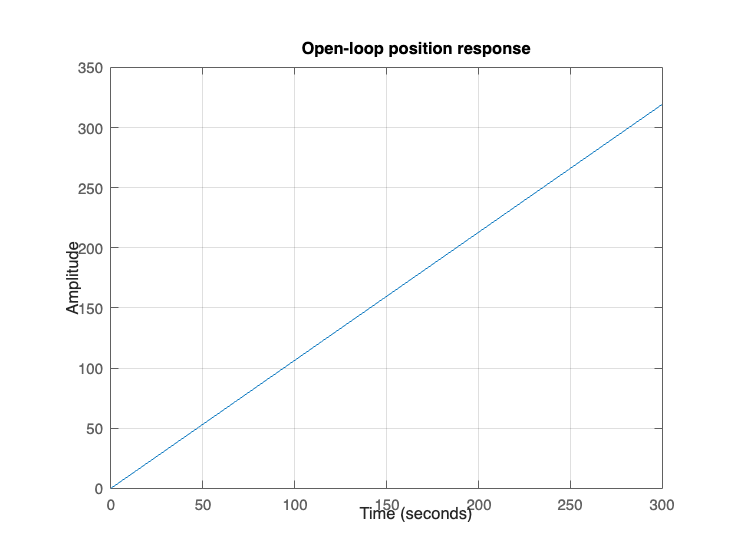


%% -------------------------
%  Example plots
%% -------------------------
figure;
step(G_theta);
grid on;
title('Open-loop position response');

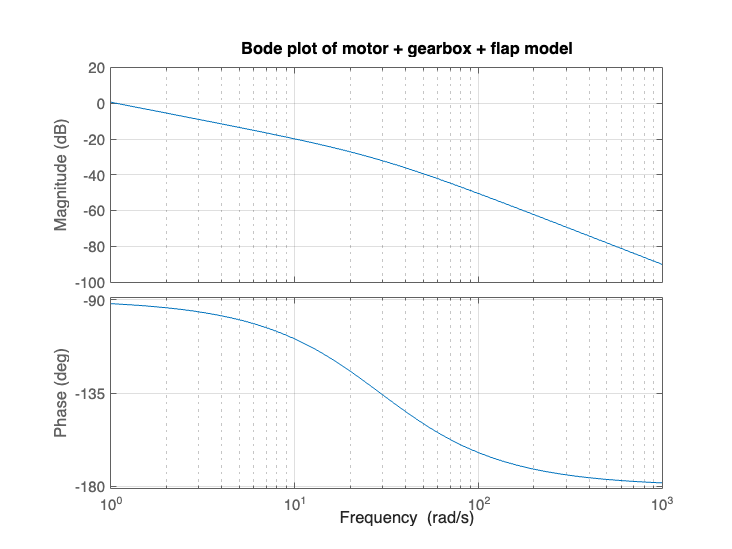


figure;
bode(G_theta);
grid on;
title('Bode plot of motor + gearbox + flap model');